s = tf('s');
F = (s-1) / ((s+0.2) * (s^3 + 2.5*s^2 +4*s))


F =
 
               s - 1
  -------------------------------
  s^4 + 2.7 s^3 + 4.5 s^2 + 0.8 s
 
Continuous-time transfer function.



Kr = 0.5;

a)

Guadagno stazionario di F

Kf = dcgain(s*F)

Kf = -1.2500

Signolarità, pulsazione e smorzamento

damp(F)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  0.00e+00                -1.00e+00       0.00e+00              Inf    
 -2.00e-01                 1.00e+00       2.00e-01         5.00e+00    
 -1.25e+00 + 1.56e+00i     6.25e-01       2.00e+00         8.00e-01    
 -1.25e+00 - 1.56e+00i     6.25e-01       2.00e+00         8.00e-01    


zero(F)

ans = 1

Diagramma di Bode per l'analisi delle frequenza iniziale e finale

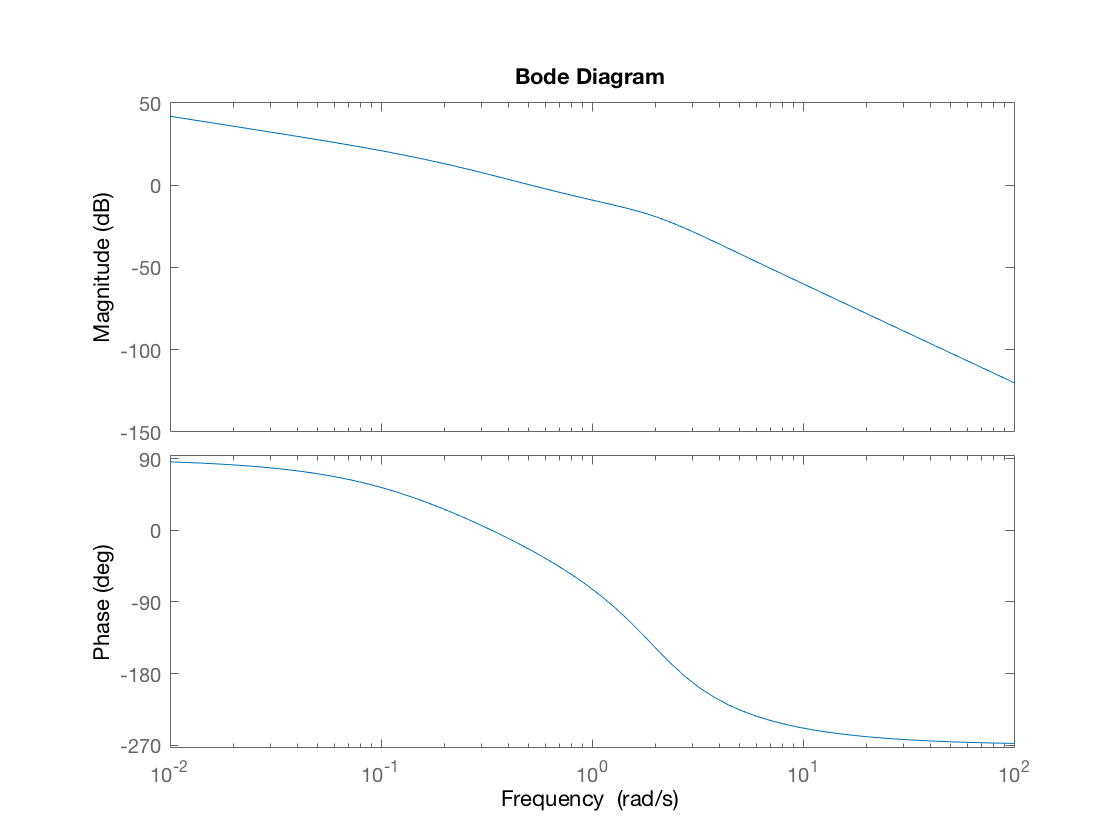

bode(F)

b)

Kc = 1;
Ga = Kc/Kr * F


Ga =
 
              2 s - 2
  -------------------------------
  s^4 + 2.7 s^3 + 4.5 s^2 + 0.8 s
 
Continuous-time transfer function.



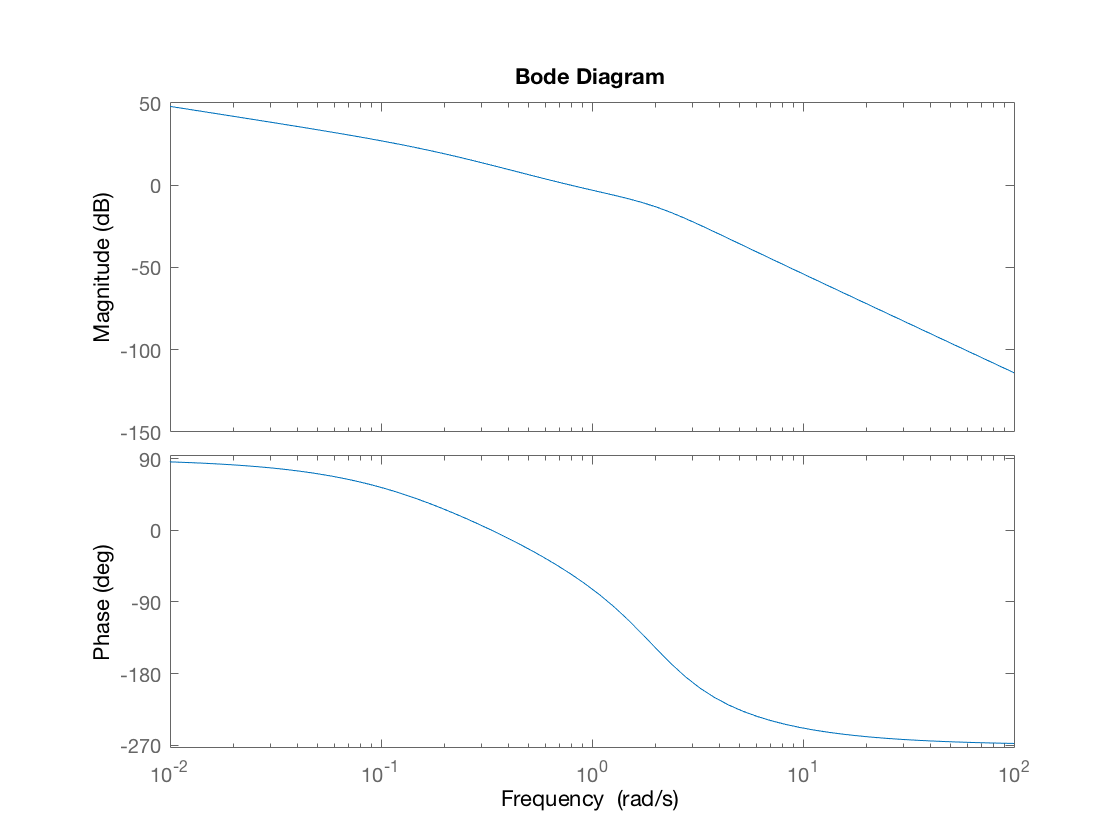

bode(Ga)

c) Diagramma di Nyquist

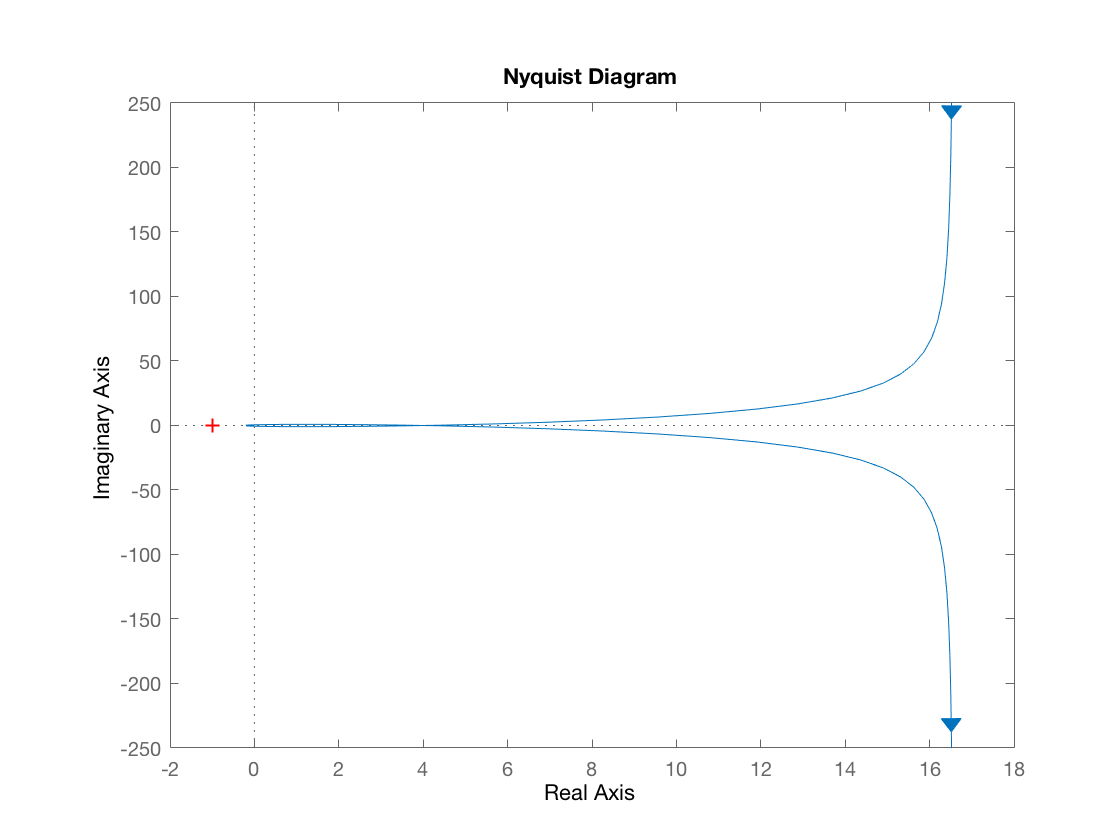

nyquist(Ga)

SI ha un attraversamento dell'asse reale a circa 4 e un altro a circa -0.11

Kc = -0.1;
W = feedback(Kc * F, 1/Kr)


W =
 
              -0.1 s + 0.1
  -------------------------------------
  s^4 + 2.7 s^3 + 4.5 s^2 + 0.6 s + 0.2
 
Continuous-time transfer function.



damp(W)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -5.72e-02 + 2.12e-01i     2.61e-01       2.19e-01         1.75e+01    
 -5.72e-02 - 2.12e-01i     2.61e-01       2.19e-01         1.75e+01    
 -1.29e+00 + 1.58e+00i     6.34e-01       2.04e+00         7.74e-01    
 -1.29e+00 - 1.58e+00i     6.34e-01       2.04e+00         7.74e-01    


e)

Funzione di trasferimento errore inseguimento

W = Kr * feedback(1, Kc*F/Kr);

Funzione di trasferimento errore dovuto a d1

W1 = feedback(F, Kc/Kr);

Funzione di trasferimento errore dovuto a d1

W2 = feedback(1, Kc/Kr * F);

e1)

r(t) = t        R(s) = 1/s^2

d1 = 0.1/s;
d2 = 0.5/s;
R = 1/s^2;
e_ins = dcgain(s * W * R)

e_ins = 2

e_d1 = dcgain(s * W1 * d1)

e_d1 = -0.5000

e_d2 = dcgain(s * W2 * d2)

e_d2 = 0

e_tot = e_ins - e_d1 - e_d2

e_tot = 2.5000

e2)

r(t) = 2        R(s) = 2/s

d1 = 0.1/s;
%d2 = 0.1t;
d2 = 1/(100*s^2);
R = 2/s;
e_ins = dcgain(s * W * R)

e_ins = 0

e_d1 = dcgain(s * W1 * d1)

e_d1 = -0.5000

e_d2 = dcgain(s * W2 * d2)

e_d2 = 0.0400

e_tot = e_ins - e_d1 - e_d2

e_tot = 0.4600